clc; clear all; close all;

% Mechanical System 7

m1 = 223; % kg
m2 = 221; % kg

k1 = 100000; % N/m
L01 = 119/1000; % m
b1 = 4000; % Ns/m^1.5

k2 = 100000; % N/m
L02 = 115/1000; % m
b2 = 4000; % Ns/m^1.5

theta = deg2rad(33); % rad
h1 = 444/1000; % m

x1 = 177/1000; % m
x1Dot = 0; % m/s

x2 = 803/1000; % m
x2Dot = 0; % m/s

g = 9.81; % m/s^2

x1DotMax = 0;

simTime = 5; % s
t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations
    % m1
    delta1 = x1 - L01;
    delta1Dot = x1Dot;

    delta2 = x2 - L01;
    delta2Dot = x2Dot;

    Fk1 = delta1 * k1;
    if(delta1 >= 0)
        Fb1 = delta1Dot * b1*sqrt(delta1);
    else
        Fb1 = 0;
    end
    Fg1 = m1*g*sin(theta);
    sumF1 = -Fk1-Fb1-Fg1;
    x1DotDot = sumF1/m1;

    % Logging
    t_plt(idx) = t;
    x1_plt(idx) = x1;
    x1Dot_plt(idx) = x1Dot;
    x2_plt(idx) = x2;
    x2Dot_plt(idx) = x2Dot;

    % Time integrate
    x1Dot = x1Dot + x1DotDot*dt;
    x1 = x1 + x1Dot*dt;

    if(abs(x1Dot) > x1DotMax)
        x1DotMax = abs(x1Dot);
    end

    % Update variables
    t = t + dt;
    idx = idx + 1;    
end
x1DotMax*1000

ans =           871.534606823499


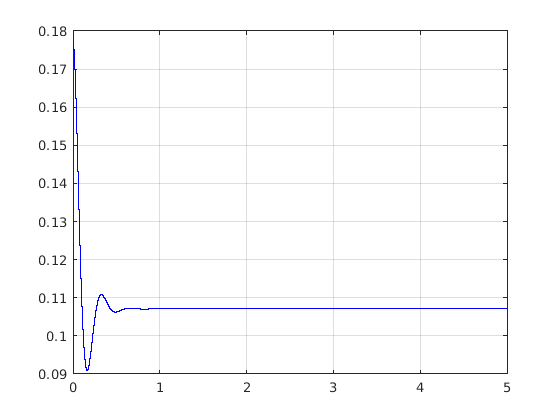

plot(t_plt, x1_plt, 'b')
grid
hold off

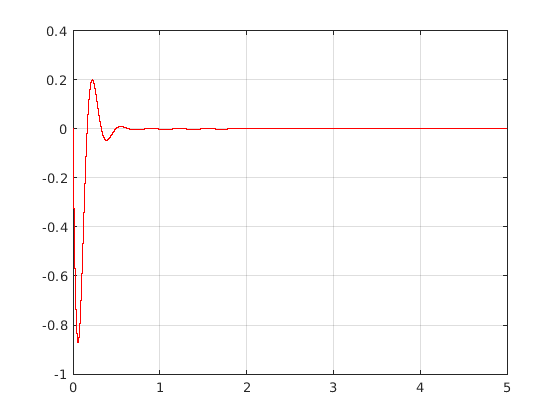

plot(t_plt, x1Dot_plt, 'r')
grid


% What is the maximum absolute value of the velocity [mm/s] of body m1 ?
abs(min(x1Dot_plt))*1000

ans =           871.534606823499


abs(max(x1Dot_plt))*1000

ans =           200.618182555673
